% Leo Beck
% Classic Monte Carlo Circle
% 2026-06-22

% The classic calculate pi with monte carlo
clear
clc

rng(0,"twister")    % choose rng method
n = 5000;           % # points
n_block = 1000;     % plotting chunks
a = -1;             % lower limit
b = 0;              % upper limit

points = (b-a)*rand(n, 2) + a;
points(n,3) = 0;
square_area = (b-a)^2

square_area = 1


% Calculate inside / outside circle
for i = 1:1:n
    if ((points(i,1)-(b+a)/2)^2 + (points(i,2)-(b+a)/2)^2 < ((b-a)/2)^2)
        points(i,3) = 1;
    end
end

% Estimate pi
in_circle = sum(points(:,3))

in_circle = 3948

pi = 4*(in_circle/n)

pi = 3.1584


% Plot circle
r = (b-a)/2;
x = (b+a)/2;
y = x;
circle(x,y,r)

ans =   Line with properties:

              Color: [0 0 0]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 -9.8664e-04 -0.0039 -0.0089 -0.0157 -0.0245 -0.0351 -0.0476 -0.0618 -0.0778 -0.0955 -0.1147 -0.1355 -0.1577 -0.1813 -0.2061 -0.2321 -0.2591 -0.2871 -0.3159 -0.3455 -0.3757 -0.4063 -0.4373 -0.4686 -0.5000 -0.5314 … ] (1×101 double)
              YData: [-0.5000 -0.4686 -0.4373 -0.4063 -0.3757 -0.3455 -0.3159 -0.2871 -0.2591 -0.2321 -0.2061 -0.1813 -0.1577 -0.1355 -0.1147 -0.0955 -0.0778 -0.0618 -0.0476 -0.0351 -0.0245 -0.0157 -0.0089 -0.0039 -9.8664e-04 0 … ] (1×101 double)

  Show all properti

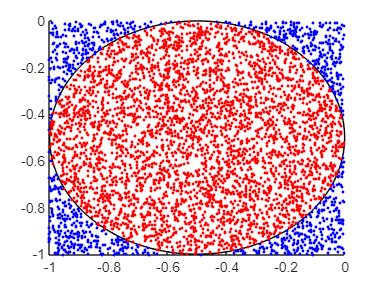

hold on

% Different groups for coloring purposed
x = points(:,1);
y = points(:,2);
in_c = points(:,3);

% Plotting
scatter(x(in_c==0), y(in_c==0), 4, "filled", "o", "blue")
hold on
scatter(x(in_c==1), y(in_c==1), 4, "filled", "o", "red")



% Circle plotting function
function h = circle(x, y, r)
hold on
th = 0:pi/50:2*pi;
xunit = r * cos(th) + x;
yunit = r * sin(th) + y;
h = plot(xunit,yunit, "Color", "black");
end